# 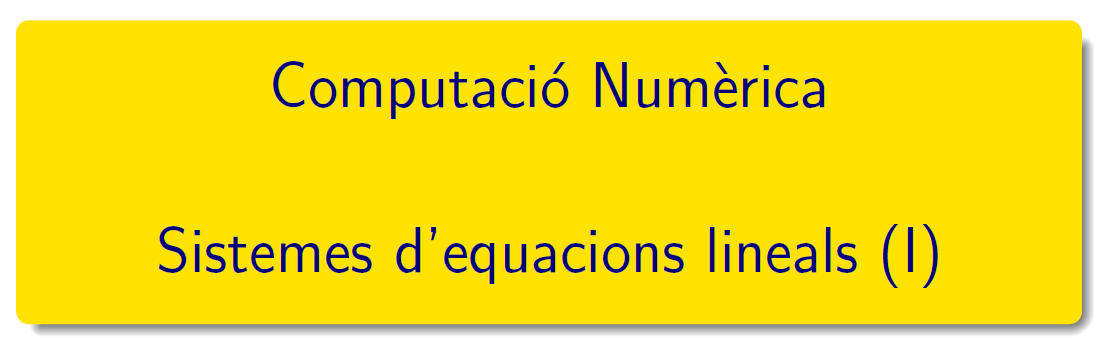

===============================================================================

# Pràctica 2  - Activitat 3: àlgebra lineal numèrica

### Aprenem ... 

### 2.1 Normes de vectors

             % vector columna de matlab
             % producte escalar = (fila x columna)
             % altres càlculs amb w i v
             % componentes del vector sin signo
% n1 = norm(v,1), sum(abs(v))         % norma 1    
% n2 = norm(v),sqrt(sum((v).^2))      % norma 2    
% n3 = norm(v,'inf'), max(abs(v))     %norma del màxim

### 2.2 Normes de matrius

Moltes matrius per exemples:  ones, eye, zero, rand, randn, magic, wilkinson, hilb, invhilb, hadamard, compan, hankel, toeplitz, gallery.

          % Matrius per exemples 
% norm(A,1),sum(A)                      % norma 1
% norm(A), sqrt(eig(A'*A))              % norma 2
% norm(A,'inf'), sum(A,2)               % norma infinit        

### Practiquem ...

#### Exercici 1.  Normes vectorials i matricials predefinits en MATLAB®

Exercici 2, pàgina 39 apunts

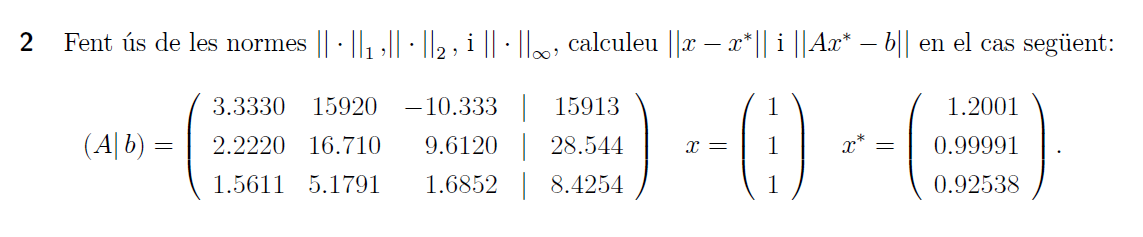

% Càlculs per fer              

### 2.3 Tipus de matrius

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius) 

Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

% Càlculs per fer

### Practiquem ...

#### Exercici 2.  Matrius i vectors predefinits en MATLAB®

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$   

- Amb zeros a  totes les seves components

% Càlculs per fer

- Amb uns a les seves components

% Càlculs per fer

- Amb nombres al·leatòris uniformes de l'interval [-2,2]

% Càlculs per fer

- Amb nombres al·leatòris normals amb $\mu = 0$ i $\sigma = 1$

% Càlculs per fer

#### Exercici 3.  Matriu triangular superior

Definiu la matriu  $U=\left(u_{ij}\right)_{15\times 15}$ i el vector  $b=(b_{i})_{15\times 1}$ com  $u_{ij}=\left\{\begin{array}{rr} \cos (ij) & i\leq j\,,\\ & \\ 0 & i>j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=\frac1{1+i^2}\,. $

% Càlculs per fer

#### Exercici 4.  Matriu triangular inferior

Definiu la matriu  $L=\left(l_{ij}\right)_{20\times 20}$ i el vector  $b=(b_{i})_{20\times 1}$ com  $l_{ij}=\left\{\begin{array}{rr} \sqrt{ij}  & i\geq j\,,\\ & \\ 0 & i<j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=2^{8-i}\,. $

% Càlculs per fer

#### Exercici 5.  Matriu quadrada 

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$ com  $a_{ij}=\left\{\begin{array}{rl} (-1)^{i} &\ i=j\,,\\ & \\ 2 &\ 1\le|i-j|\le 2\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=i\,.$

% Càlculs per fer

#### Exercici 6. Tranformacions ortogonals

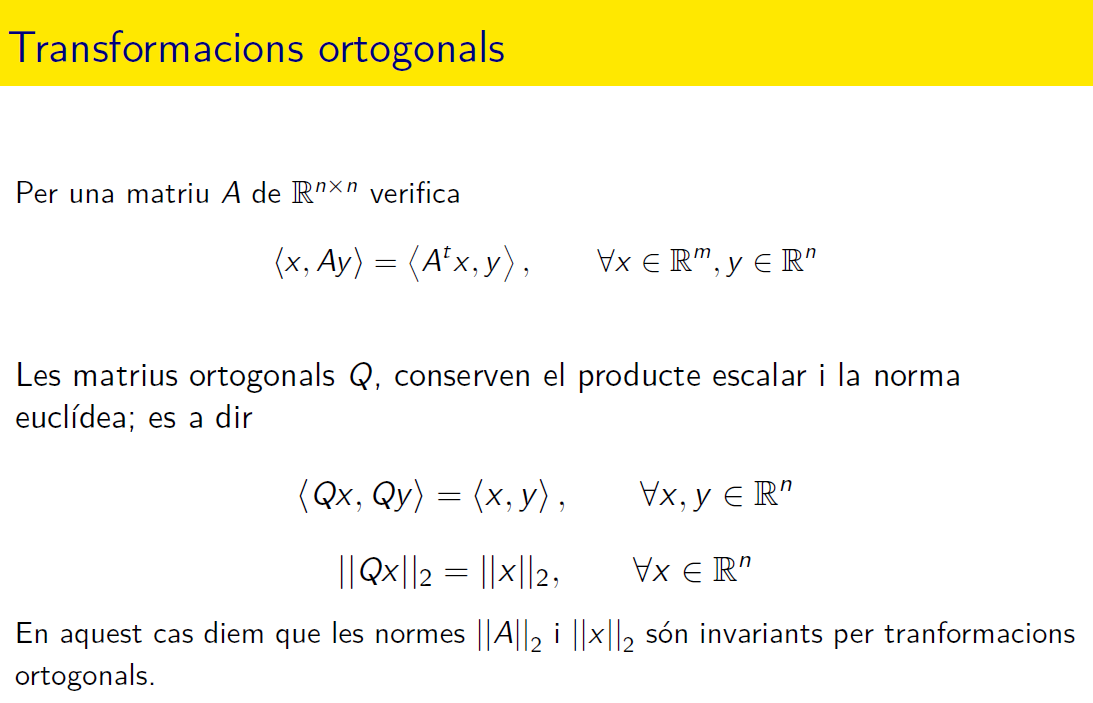

a) Verifica la propietat <x,Ay> = <A^tx,y> per a qualsevol matriu A quadrada.

format shortG
% A = gallery('lehmer',5)     % Una matriu de la biblioteca
% x = ones(5,1); y = diag(hilb(5));   [x,y]  % dos vectors columna


b) Verifica la propietat <Qx,Qy> = <x,y> per a qualsevol matriu Q ortogonal.

% Q = gallery('orthog',6)    % Una matriu ortogonal de la biblioteca
% x = ones(6,1); y = diag(hilb(6)); [x,y]      % dos vectors columna
 

### 2.4 Resolució de sistemas d'equacions lineals 

### Aprenem ...

#### Exercici 7: funcions de  MATLAB®

Calculeu  el determinant, la transposta, la inversa, els valors propis i els vectors propis de la matriu A definida per

$\displaystyle A=\left(\begin{array}{rrr} 1 & 2 & 1\\ -2 & 7 & 3\\ 1 &-1 &10 \end{array}\right)$    )Exercici 1, pàgina 41)

% Càlculs per fer
 

#### Exercici 8. **Propagació de l'error. Sistema lineal mal condicionat.**

. Resoleu el sistema $\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6.001y&=&2 \\\end{array}\right.$   fent ús de la instrucció [linsolve](https://es.mathworks.com/help/matlab/ref/linsolve.html) de  MATLAB®

Compareu la solució  amb la del sistema  $\left\{\begin{array}{rcrcr}2x&-&4y&=&1 \\ -2.998x&+&6y&=&2 \\\end{array}\right.$. Com són les dues solucions? 

És un problema estable?    (Exercici1, pàgina 39)

Calculeu el nombre de condició de la matriu associada al sistema lineal.  

% Càlculs per fer

#### Nombre de condició d'una matriu

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format shortG
% H = hilb(4);
% condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

### **Practiquem ... **

**Vector residu i nombre de condició**

- `Exercici 9.` Estudiem com varia la solució del sistema lineal quan modifiquem només el terme independent $A(x+\delta x) = b+\delta b$


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


format shortG
% Càlculs per fer

- `Exercici 10.` Estudieu com varia la solució del sistema lineal quan modifiquem només la matriu del sistema $(A+\Delta)(x+\delta x) = b$ 


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.01& 7.02 & 32\\
7.08 & 5.04 & 6 & 5 & 23\\
8 & 5.98 & 9.89 & 9 & 33\\
6.99 & 4.99 & 9 & 9.98& 31\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


% Càlculs per fer


- `Exercici 11.` Estudiem com varia la solució del sistema lineal quan modifiquem  la matriu del sistema i el terme independent$(A+\Delta)(x+\delta x) = b+\delta b$


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.01& 7.02 & 32.1\\
7.08 & 5.04 & 6 & 5 & 22.9\\
8 & 5.98 & 9.89 & 9 & 33.1\\
6.99 & 4.99 & 9 & 9.98& 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


% Càlculs per fer

## Per fer ...

De la llista de problemes del tema 2:

- pàgina 39, exercicis 1 i 2, 

- pàgina 41, exercicis del 1 al 5

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`